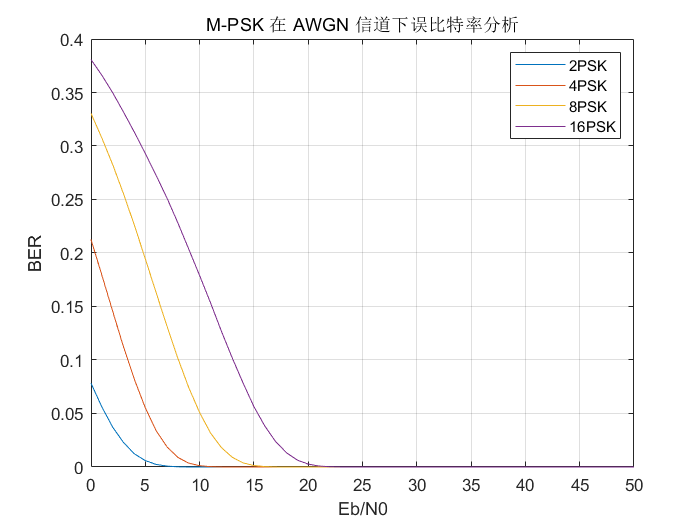

% M 进制 PSK 调制参数设置
N = 1000000;                        % 仿真点数
B = 2;                             % PSK 进制数                   
A2 = B - 1;                         % PSK 调制数据的最大幅值
data2 = randi([0, A2], N, 1);        %产生随机信号
Q = 4;                             % PSK 进制数
A4 = Q - 1;                         % PSK 调制数据的最大幅值
data4 = randi([0, A4], N, 1);        %产生随机信号
E = 8;                             % PSK 进制数
A8 = E - 1;                         % PSK 调制数据的最大幅值
data8 = randi([0, A8], N, 1);        %产生随机信号
S = 16;                             % PSK 进制数
A16 = S - 1;                         % PSK 调制数据的最大幅值
data16 = randi([0, A16], N, 1);        %产生随机信号

% 信噪比变化范围
SNR = 0:1:50;

% M 进制 PSK 调制
modData2 = pskmod(data2, B);
modData4 = pskmod(data4, Q);
modData8 = pskmod(data8, E);
modData16 = pskmod(data16, S);

% 在不同信噪比下进行仿真
for i = 1:length(SNR)
    % AWGN信道，'measured'代表加入噪声前测量信号能量
    rxSig2 = awgn(modData2, SNR(i), 'measured');
    % M 进制 PSK 解调
    rxData2 = pskdemod(rxSig2, B);
    % 统计误码比特数以及误码率
    [err_bit2(i), err_rate2(i)] = biterr(data2, rxData2);
    
    % AWGN信道，'measured'代表加入噪声前测量信号能量
    rxSig4 = awgn(modData4, SNR(i), 'measured');
    % M 进制 PSK 解调
    rxData4 = pskdemod(rxSig4, Q);
    % 统计误码比特数以及误码率
    [err_bit4(i), err_rate4(i)] = biterr(data4, rxData4);
    
    % AWGN信道，'measured'代表加入噪声前测量信号能量
    rxSig8 = awgn(modData8, SNR(i), 'measured');
    % M 进制 PSK 解调
    rxData8 = pskdemod(rxSig8, E);
    % 统计误码比特数以及误码率
    [err_bit8(i), err_rate8(i)] = biterr(data8, rxData8);
    
    % AWGN信道，'measured'代表加入噪声前测量信号能量
    rxSig16 = awgn(modData16, SNR(i), 'measured');
    % M 进制 PSK 解调
    rxData16 = pskdemod(rxSig16, S);
    % 统计误码比特数以及误码率
    [err_bit16(i), err_rate16(i)] = biterr(data16, rxData16);
end

% 绘制误比特率与信噪比曲线，纵轴为对数尺度
plot(SNR ,err_rate2);hold on;
plot(SNR,err_rate4);hold on;
plot(SNR ,err_rate8);hold on;
plot(SNR ,err_rate16);hold on;
legend('2PSK','4PSK','8PSK','16PSK');grid on;
title('M-PSK 在 AWGN 信道下误比特率分析');
xlabel('Eb/N0');ylabel('BER');